# Chapter 4

*Original author: Allen Downey (2017)*

*Author: Zachary del Rosario (2020)*

% Set the random state
rng(101)

% NOTE: If this cell is successful, it produces no output

## Returning Values

We've played *fast and loose* with return values so far; let's look a little closer at function syntax. Take a look at the following two example function signatures:

% NOTE: No need to edit this
% function fcn_fruitless(x)
%     disp(x)
% end

This function `fcn_fruitless` does not have a return value defined; it's similar to functions like `plot()`, where we call it for some side effect, but don't assign its output to any value.

The next function is different in character:

% NOTE: No need to edit this
% function res = fcn_fruitful(x)
%     res = x .^ 2;
% end

This function `fcn_fruitful` **does** return a value; if we want to take advantage of this function, we should probably use its result in later computation, or at least assign it to a variable,e.g. `y = fcn_fruitful(2)`.

We've seen use-cases for both kinds of functions. Functions with no return like `plt_record()` are quite useful for visualizing our results. Functions like `fcn_simulate()` automate a lot of steps to return some data. Using both kinds of functions will help us abstract away details so we can concentrate on running simulations.

## Running Simulations

The folder with this notebook contains the files from the last notebook, so we can easily run simulations. We can set up, simulate, and visualize results with a few lines:

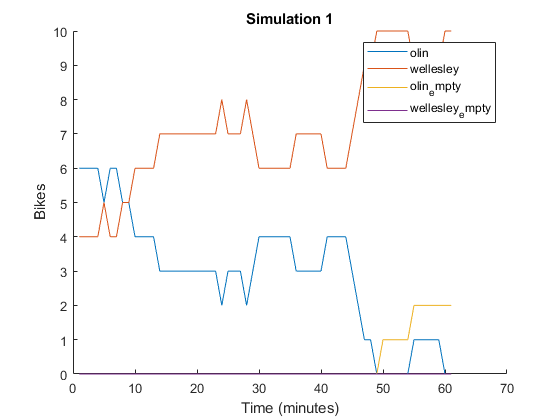

% Set up the initial state
tab_state = fcn_make_table( ...
    "olin", 6, ...
    "wellesley", 4, ...
    "olin_empty", 0, ...
    "wellesley_empty", 0 ...
);
% Run the simulation
tab_record = fcn_simulate(tab_state, 0.4, 0.2, 60);
% Visualize
plt_record(tab_record);
title("Simulation 1")

Now we can edit the parameters to investigate different settings; when `p_o2w` (probability of biking from **O**lin **to** **W**ellesley) is low we probably don't run out of bikes at Olin:

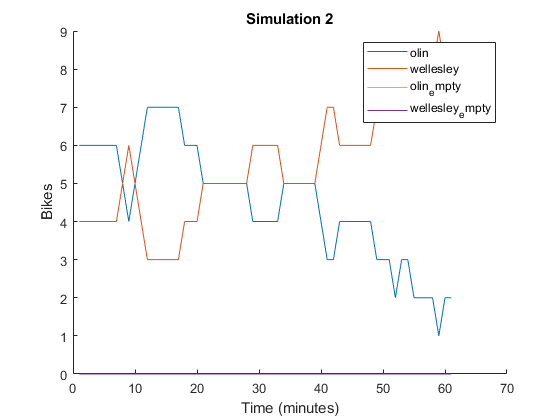

tab_record2 = fcn_simulate(tab_state, 0.2, 0.2, 60);
plt_record(tab_record2);
title("Simulation 2")

But if we increase `p_o2w`, we'll probably see some unhappy Oliners:

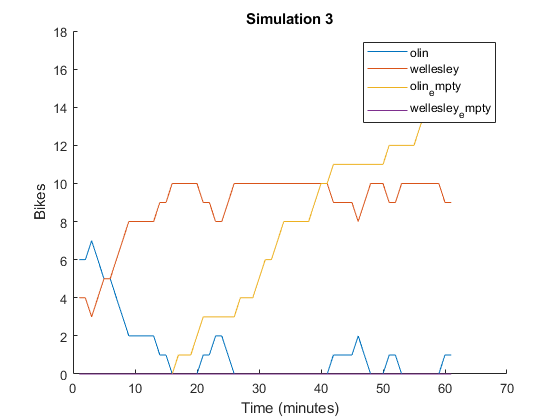

tab_record3 = fcn_simulate(tab_state, 0.5, 0.2, 60);
plt_record(tab_record3);
title("Simulation 3")

We can access the count of unhappy Oliners with dot notation:

tab_record3.olin_empty

ans =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


And if we wanted to see the state at the end of the simulation, we could use the special syntax `end`:

tab_record3.olin_empty(end)

ans = 17

This tells us that at the end of `tab_record3` there were this many Oliners who tried to use the bikeshare, only to find no bike available. To take the last row of the table, we can instead use `(row, column)` syntax

tab_record3(end, :)

ans = 1×4 table
    olin    wellesley    olin_empty    wellesley_empty
    ____    _________    __________    _______________

     1          9            17               0       


Which gives us the `end` of the rows, and all of the columns using the special colon (`:`) syntax.

**Exercise:** Use the "end of table" notation to display the end state of `tab_record2`.

% SOLUTION
tab_record2(end, :)

ans = 1×4 table
    olin    wellesley    olin_empty    wellesley_empty
    ____    _________    __________    _______________

     2          8            0                0       


We might like to know how this count of missed opportunities changes across different simulation settings: To do this, we need to learn how to do a *parameter sweep*, which will require some more work with for loops.

## Helpers with For loops

The Matlab built-in function `linspace` will help us run more involved simulations; it creates a set of values **lin**early **space**d between two values. For instance:

linspace(0, 1)

ans =          0    0.0101    0.0202    0.0303    0.0404    0.0505    0.0606    0.0707    0.0808    0.0909    0.1010    0.1111    0.1212    0.1313    0.1414    0.1515    0.1616    0.1717    0.1818    0.1919    0.2020    0.2121    0.2222    0.2323    0.2424    0.2525    0.2626    0.2727    0.2828    0.2929    0.3030    0.3131    0.3232    0.3333    0.3434    0.3535    0.3636    0.3737    0.3838    0.3939    0.4040    0.4141    0.4242    0.4343    0.4444    0.4545    0.4646    0.4747    0.4848    0.4949


By default `linspace` gives us 100 values; we can specify how many we want with an optional third parameter:

linspace(0, 1, 4)

ans =          0    0.3333    0.6667    1.0000


**Exercise:** Use `linspace` to create a set of 20 values from 1 to 10.

% SOLUTION
t10 = linspace(1, 10, 20);

% NOTE: The following will NOT throw an error if your answer is correct
assert(t10(1) == 1)
assert(t10(end) == 10)
assert(length(t10) == 20)

We can use this with a `for` loop to *sweep *over a range of values; for instance, the following code computes the squares for a range of values.

for x = linspace(1, 5, 5)
    disp(x ^ 2);
end

     1

     4

     9

    16

    25



Using the same ideas, we can sweep through *model parameters* while running simulations.

## Sweeping Parameters

Using `linspace` we can define a range of values to try with our simulation. For instance, suppose we wanted to try a range of values

p_o2w_sweep = linspace(0.2, 0.5, 10)

p_o2w_sweep =     0.2000    0.2333    0.2667    0.3000    0.3333    0.3667    0.4000    0.4333    0.4667    0.5000


We can combine the ideas above to perform a *parameter sweep*: To do so, we'll:

- Use the range of values `p_o2w_sweep` in a for loop

- Use the convenient simulation function we built to run a simulation

- Extract the end state of the simulation

- Store the results in a table

The following code puts all these ideas together:

rng(103)
% Create empty table to hold results
tab_olin_sweep = fcn_make_table();

% Do the parameter sweep
for p_o2w = p_o2w_sweep
    % Run the simulation
    tab_record_tmp = fcn_simulate(tab_state, p_o2w, 0.2, 60);
    % Extract the last row of the record
    tab_end = tab_record_tmp(end, :);
    % Note the value of p_o2w we used to simulate
    tab_end.p_o2w = p_o2w;
    % Store the results
    tab_olin_sweep = [tab_olin_sweep; tab_end];
end

% The following syntax prints just two of the columns
tab_olin_sweep(:, ["p_o2w", "olin_empty"])

ans = 10×2 table
     p_o2w     olin_empty
    _______    __________

        0.2         0    
    0.23333         0    
    0.26667         0    
        0.3         0    
    0.33333         3    
    0.36667         7    
        0.4        14    
    0.43333         1    
    0.46667        17    
        0.5         9    


**Consider the following:** How would you expect `olin_empty` to change with `p_o2w`? Do the results align with your expectations?

**Exercise:** Now it's your turn! Perform a sweep for `p_w2o` from `0.2` to `0.5`, while keeping `p_o2w = 0.3` fixed. Store the results in `tab_wellesley_sweep` and display the results.

% SOLUTION
% Create empty table to hold results
p_w2o_sweep = linspace(0.2, 0.5, 10);
tab_wellesley_sweep = fcn_make_table();

% Do the parameter sweep
for p_w2o = p_w2o_sweep
    % Run the simulation
    tab_record_tmp = fcn_simulate(tab_state, 0.3, p_w2o, 60);
    % Extract the last row of the record
    tab_end = tab_record_tmp(end, :);
    tab_end.p_w2o = p_w2o;
    % Store the results
    tab_wellesley_sweep = [tab_wellesley_sweep; tab_end];
end

% The following syntax prints just two of the columns
tab_wellesley_sweep(:, ["p_w2o", "wellesley_empty"])

ans = 10×2 table
     p_w2o     wellesley_empty
    _______    _______________

        0.2           0       
    0.23333           0       
    0.26667           0       
        0.3           3       
    0.33333           1       
    0.36667           0       
        0.4           3       
    0.43333          10       
    0.46667           4       
        0.5           7       


You might notice that the number of `empty` occurrences doesn't change consistently! That's because we're running *random simulations*.

## Random Simulations

At first blush, we'd expect the count of `empty` to increase as we increase the probability of a biker looking for a cycle. While that's true *on average*, we're only considering the results of single *random* *simulations*. Remember that inside the *bowels* of the bikeshare simulation, we're using the `coin` function to make decisions:

rng(101)
% We're going to get different results if we re-run coin()
coin(0.5)

ans = 0

coin(0.5)

ans = 0

coin(0.5)

ans = 1

This means that if we run a random simulation twice with *identical* settings, we're almost surely going to see different results:

rng(101)
tab_run1 = fcn_simulate(tab_state, 0.5, 0.2, 60);
tab_run2 = fcn_simulate(tab_state, 0.5, 0.2, 60);

Each of these individual runs, here documented by `tab_run1` and `tab_run2, `are called **realizations**`. `We can compare the end state of these two realizations:

tab_run1.olin_empty(end)

ans = 6

tab_run2.olin_empty(end)

ans = 18

Indeed, we can see their end states are quite different. This points to an *extremely important principle*:

**A single realization is ****almost**** meaningless.**

If you handed me a 6-sided die and I rolled it once then told you "This die rolls 3's," you would rightly call me a crazy person. Running a random simulation once is just like that.

Performing a single run of a random simulation is useful for model-building and testing purposes, but in order to do serious science, we have to account for the randomness. To that end, we can perform *replications*.

## Replications

To generate **replications **we use a lot of the same ideas from parameter sweeping. However, instead of changing simulation parameters, we *keep simulation parameters fixed*, and simply *re-run the simulation.* The following code runs a replication study.

% Run a number of replications
p_o2w = 0.3; p_w2o = 0.2;
n_replications = 50;
tab_rep = fcn_make_table();

% 
for rep = 1 : n_replications
    % NOTE: We run the simulation with *identical* parameters every time
    tab_record_tmp = fcn_simulate(tab_state, p_o2w, p_w2o, 60);
    % Extract the last row of the record
    tab_end = tab_record_tmp(end, :);
    tab_end.rep = rep;
    % Store the results
    tab_rep = [tab_rep; tab_end];
end

% Despite running with identical parameters, we get different results!
tab_rep(:, ["rep", "olin_empty", "wellesley_empty"])

ans = 50×3 table
    rep    olin_empty    wellesley_empty
    ___    __________    _______________

     1          7               0       
     2          0               0       
     3          2               0       
     4          5               0       
     5          1               0       
     6          4               0       
     7          4               0       
     8          0               0       
     9          1               0       
    10         10               0       
    11          0               0       
    12          2               0       
    13          0               0       
    14          2               0       
    15         12               0       
    16          3               0       


To help make sense of these replications, you can use the provided `describe()` function.

describe(tab_rep(:, ["olin_empty", "wellesley_empty"]))

ans = 6×3 table
    olin_empty    wellesley_empty      stat  
    __________    _______________    ________

         12               7          "Max"   
          4               0          "Q3"    
       2.34            0.18          "Mean"  
          1               0          "Median"
          0               0          "Q1"    
          0               0          "Min"   


These results indicate that the typical (mean) number of misses we tend to see at Olin is a little over 2, but we could see as many as 12 misses over the simulation period.